# **demo08 of Im2mesh package**

demo08 - Function plotMeshes

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Overview

We will demostrate function plotMeshes in this demo.

There are 3 typical usage of function plotMeshes

% usage 1:
%   plotMeshes( vert, ele, tnum );
%
% usage 2:
%   plotMeshes( vert, ele, tnum, color_code );
%
% usage 3:
%   plotMeshes( vert,ele,tnum, color_code, opt )

The meanings of the input arguments are as follows:

    color_code: Color code for selecting colormap. Interger. Value: 0-10. Default value: 0

                        0: grayscale, 1: lines, 2: parula, 3: turbo, 4: jet, 5: hot, 6: cool, 7: summer, 8: winter, 9: bone, 10: pink.

    opt: a structure array. It is the extra options for plotMeshes. It stores extra parameter settings for plotMeshes.

    opt.mode: display mode. Value: 1 or 2.

    opt.wid: line width of the plotted edges. Default value: 0.5

    opt.alpha: edge line transparency. It's a scalar value in range [0,1]. Default value: 0.5

    opt.beta: brightness adjustment of colormap. [-1, 1]. Default value: 0

    opt.tf_gs: Boolean value. Whether to use graphics smoothing when plotting. Default value: 1

    opt.q_thresh: threshold for mesh quality. Those elements with mesh quality lower than opt.q_thresh will be highlighted. Default value: 0

## Import image

Let's start demo. Import image.

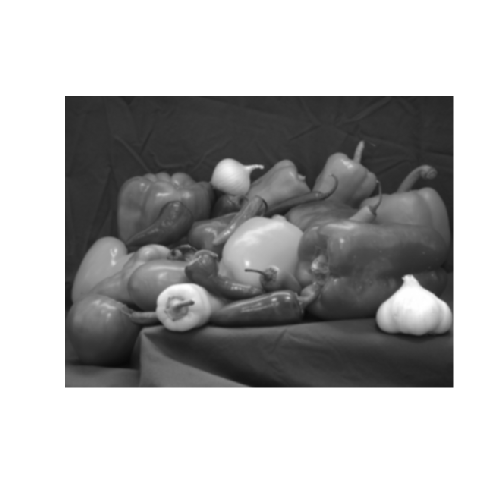

im = imread('Pepper.png');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Image segmentation

Otsu’s method

num_phase = 2;  % number of phases
thresh = multithresh( im, num_phase-1 ); 
im_temp = imquantize( im, thresh );
im_seg = uint8( mat2gray(im_temp) * 255 );

Show segmented image

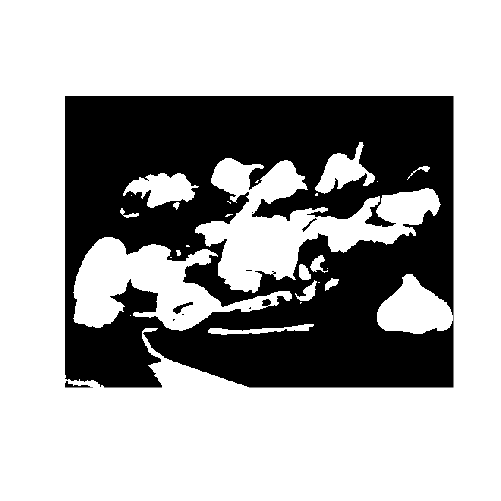

imshow( im_seg,'InitialMagnification','fit' );

## Generate mesh

opt = [];   % reset
opt.grad_limit = 1;

[ vert, tria, tnum ] = im2mesh( im_seg, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10               1262               2266
         10               1262               2266
         20               1412               6271
         20               1412               6271


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10               1849               2266
         15               1860               2266
         20               1964              10982
         30               2023              13291
         34               2023              13311


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -----------

Plot mesh

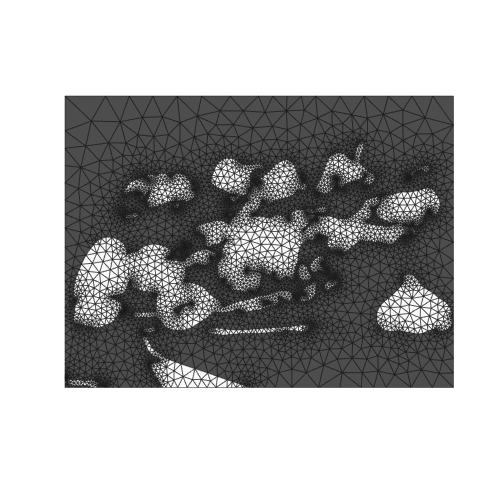

plotMeshes( vert, tria, tnum )

## Set colormap

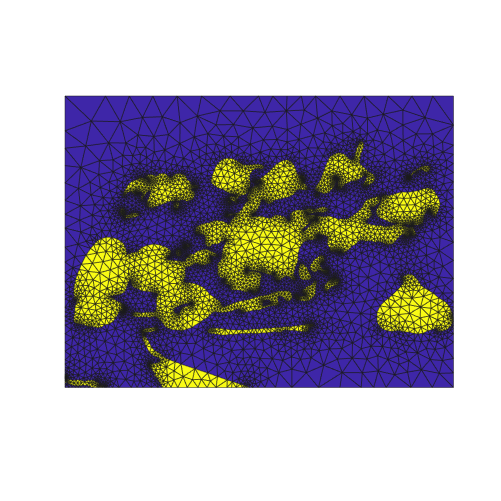

color_code = 2;
plotMeshes( vert,tria,tnum, color_code )

## Set mode

When opt.mode=1, plot faces and edges. Slower.

When opt.mode=2, plot edges only. Faster.

Default value: 1

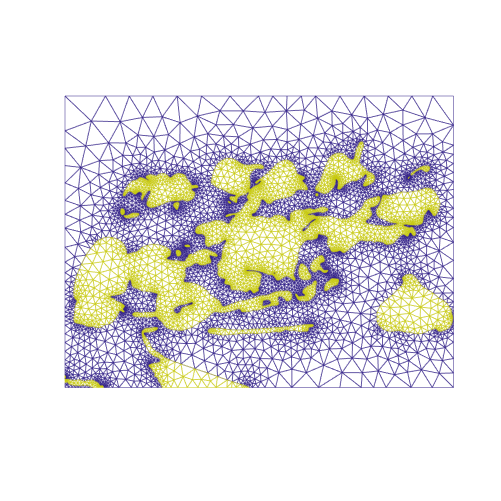

color_code = 2;
opt = [];   % reset
opt.mode = 2;

plotMeshes( vert,tria,tnum, color_code, opt ) 

## Set other plot styles

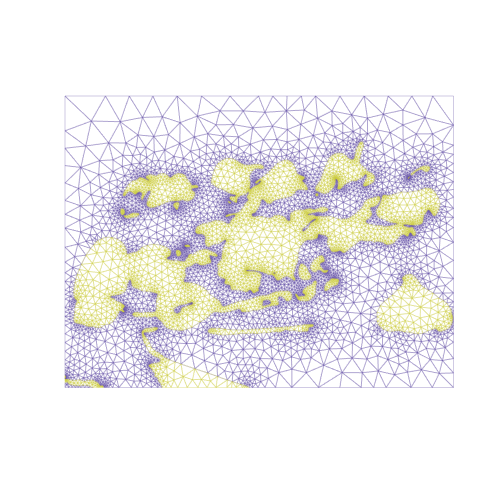

color_code = 2;

opt = [];   % reset
opt.mode = 2;
opt.wid = 0.5;
opt.alpha = 0.3;
opt.beta = 0.5;

plotMeshes( vert,tria,tnum, color_code, opt )

## Display low quality elements

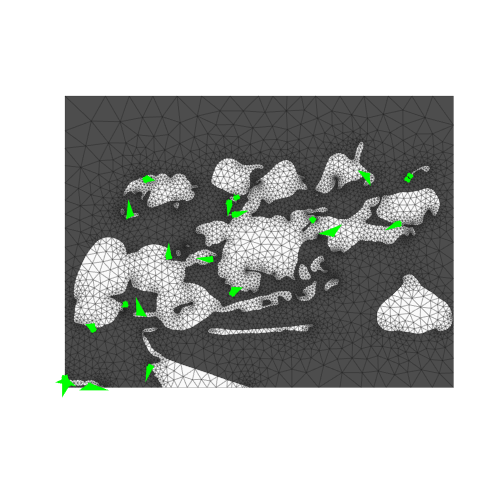

color_code = 0;

opt = [];   % reset
opt.mode = 1;
opt.wid = 0.5;
opt.alpha = 0.2;
opt.beta = 0;
opt.q_thresh = 0.7;

plotMeshes( vert,tria,tnum, color_code, opt )

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo